clear;
close all;
clc;

% The root directory of the dataset
root_dir = fullfile("p_dataset_26/");

% Load the dataset 
dataset = imageDatastore(root_dir, "IncludeSubfolders", true, "LabelSource", "foldernames");

% Counting the number of images for every label and displaying it on a table
table = countEachLabel(dataset);
disp(table);

    Label    Count
    _____    _____

      0       254 
      4       254 
      7       254 
      8       254 
      A       254 
      D       254 
      H       254 



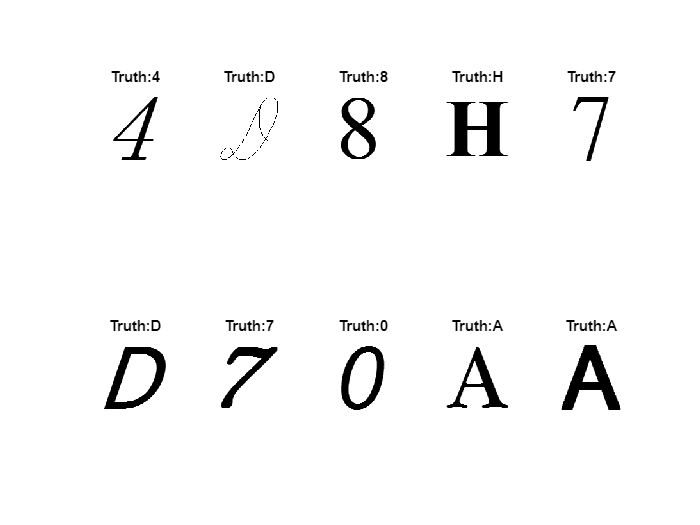


% Randomize 10 numbers and generate total number of images in the dataset 
random__num = randperm(sum(table.Count), 10);
figure;
for i = 1:10 
    subplot(2, 5, i);
    imshow(dataset.Files{random__num(i)}); % Divide into 2x5 grid of subplot
    title(['Truth:' char(dataset.Labels(random__num(i)))]);
end


% Dividing the dataset into training set and test (validation) set 
% Training set: test set = 0.75 : 0.25
[trainset, testset] = splitEachLabel(dataset, 0.75, "randomized");

% Reading and flattening images for PCA
train_num = numel(trainset.Files);
test_num = numel(testset.Files);
imageSize = [64, 64]; % Change this size as needed

train_images = zeros(train_num, prod(imageSize));
for i = 1:train_num
    img = readimage(trainset, i);
    img = imresize(img, imageSize);
    train_images(i, :) = img(:)';
end

% Apply PCA
[coeff, score, ~, ~, ~] = pca(double(train_images));


% Retain 95% variance
numComponents = find(cumsum(sum(score.^2,1)./sum(score(:).^2)) >= 0.95, 1, 'first');
train_pca = score(:, 1:numComponents);

train_labels = grp2idx(trainset.Labels);

% Train SVM with PCA features
SVM = fitcecoc(train_pca, train_labels);

% Prepare test data for PCA
test_images = zeros(test_num, prod(imageSize));
for j = 1:test_num
    img = readimage(testset, j);
    img = imresize(img, imageSize);
    test_images(j, :) = img(:)';
end

% Applying PCA transformation
test_pca = double(test_images) * coeff(:, 1:numComponents);

% Predict with SVM
predicted_label = predict(SVM, test_pca);

% Evaluate accuracy
test_label = grp2idx(testset.Labels);
accuracy = sum(predicted_label == test_label) / numel(test_label);
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.53741


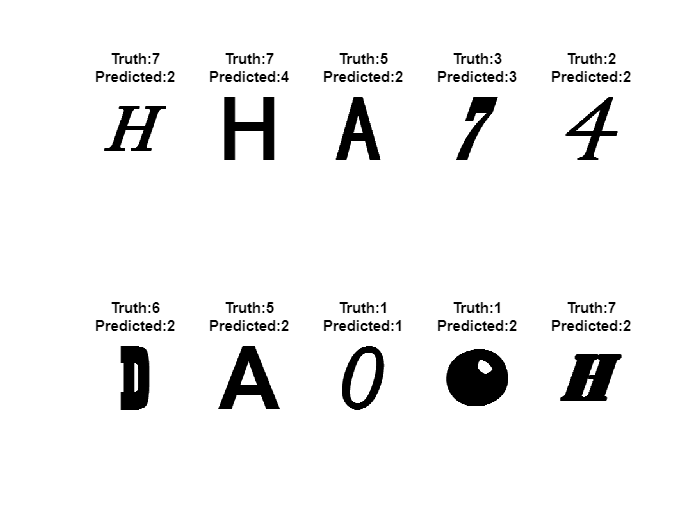


% Predicted Labels vs Actual Labels
random_num = randperm(numel(predicted_label), 10);
figure;
for i = 1:10
    subplot(2, 5, i);
    imshow(testset.Files{random_num(i)});
    title({['Truth:' num2str(test_label(random_num(i)))], ['Predicted:' num2str(predicted_label(random_num(i)))]});
end

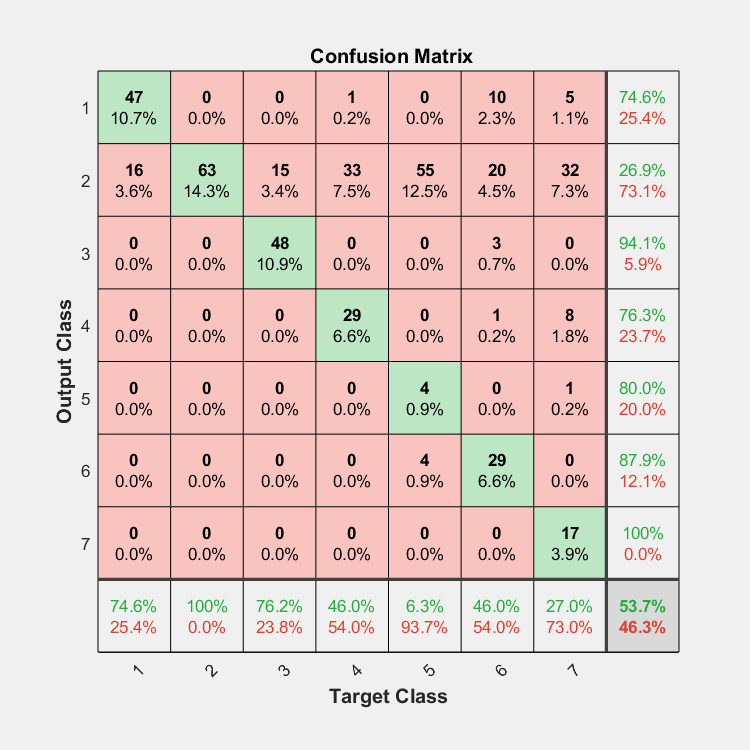


% Confusion matrix for performance evaluation
figure;
plotconfusion(ind2vec(test_label'), ind2vec(predicted_label'));

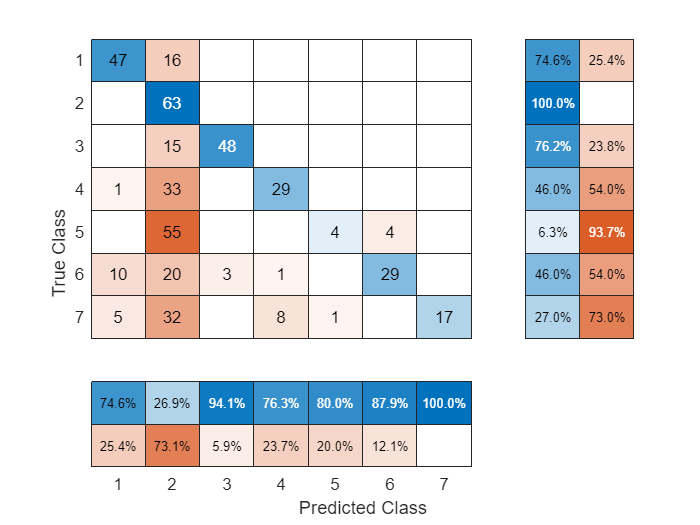


% Confusion chart for performance evaluation
figure;
confMat = confusionmat(test_label, predicted_label);
chart = confusionchart(confMat, 'RowSummary','row-normalized','ColumnSummary','column-normalized');


% Saving SVM
% SVM_PCA = SVM;
% save SVM_PCA
